clc; clear;
load("C:\Users\Fabian\Desktop\SoaringCPP\autonomous-soaring\Calculations\Sim_daten\2024-02-13 23-47-28.bin-172743.mat")


res = GPS_0(:,5)/1000 % convert to seconds

res = 1.0e+05 *

    2.5487
    2.5487
    2.5487
    2.5487
    2.5487
    2.5487
    2.5487
    2.5487
    2.5487
    2.5487


res = res/3600 % convert to minutes

res =    70.7962
   70.7963
   70.7963
   70.7964
   70.7964
   70.7965
   70.7966
   70.7966
   70.7967
   70.7967


res = mod(res,24) % get the time only from the current day

res =    22.7962
   22.7963
   22.7963
   22.7964
   22.7964
   22.7965
   22.7966
   22.7966
   22.7967
   22.7967




% Initialize an array for the converted times
convertedTimes_Week = res

convertedTimes_Week =    22.7962
   22.7963
   22.7963
   22.7964
   22.7964
   22.7965
   22.7966
   22.7966
   22.7967
   22.7967


convertedTimes_WeekTEST = res

convertedTimes_WeekTEST =    22.7962
   22.7963
   22.7963
   22.7964
   22.7964
   22.7965
   22.7966
   22.7966
   22.7967
   22.7967



% Loop through each value and convert to hours.minutes format
for i = 1:length(res)
    % Extract the integer part (hours)
    hours = floor(res(i));

    % Extract the decimal part (fraction of an hour)
    fractionOfHour = res(i) - hours;

    % Convert the fraction of an hour to minutes and seconds
    %minutes = floor(fractionOfHour * 60);
    %seconds = (fractionOfHour * 60 - minutes) * 60;

    % Store the result in the new array
    %convertedTimes_Week(i) = hours + minutes / 100 + seconds / 10000;
    convertedTimes_WeekTEST = hours+fractionOfHour;
end
convertedTimes_Week = GPS_0(:,5) % milliseconds since start of GPS Week

convertedTimes_Week =    254866400
   254866600
   254866800
   254867000
   254867200
   254867400
   254867600
   254867800
   254868000
   254868200


convertedTimes = GPS_0(:,2)

convertedTimes =    151447726
   151647645
   151847353
   152048084
   152247428
   152448032
   152648041
   152847666
   153047928
   153247338


% Timestamp US
T = table(convertedTimes,convertedTimes_Week,GPS_0(:,11),GPS_0(:,9),GPS_0(:,10),GPS_0(:,12),GPS_0(:,13), 'VariableNames', {'Timestamp','Timestamp Daytime','ALT','Lat','Long','G-Speed [m/s]','GroundCourse'})

T = 963×7 table
    Timestamp     Timestamp Daytime     ALT       Lat       Long     G-Speed [m/s]    GroundCourse
    __________    _________________    ______    ______    ______    _____________    ____________

    1.5145e+08       2.5487e+08        444.75    47.343    8.2572            0           218.36   
    1.5165e+08       2.5487e+08        444.75    47.343    8.2572        0.001           85.163   
    1.5185e+08       2.5487e+08        444.75    47.343    8.2572        0.001            76.51   
    1.5205e+08       2.5487e+08        444.75    47.343    8.2572            0           239.63   
    1.5225e+08       2.5487e+08        444.75    47.343    8.2572        0.002            253.9   
    1.5245e+08       2.5487e+08        444.75    47.

% Fixing Alt that it over ground
T.ALT = T.ALT - T.ALT(1);

GyroX =nan(1,length(GPS_0(:,2)));
GyroY =nan(1,length(GPS_0(:,2)));
GyroZ =nan(1,length(GPS_0(:,2)));
AcceX =nan(1,length(GPS_0(:,2)));
AcceY =nan(1,length(GPS_0(:,2)));
AcceZ =nan(1,length(GPS_0(:,2)));


for i = 1:length(GyroX)
    timestampTable = GPS_0(i,2);
    for j = 1:length(IMU_1(:,2))
        if timestampTable == IMU_1(j,2)
            GyroX(i) = IMU_1(j,4);
            GyroY(i) = IMU_1(j,5);
            GyroZ(i) = IMU_1(j,6);
            AcceX(i) = IMU_1(j,7);
            AcceY(i) = IMU_1(j,8);
            AcceZ(i) = IMU_1(j,9);
        end
    end
end
GyroX

GyroX =     0.0021    0.0020    0.0020    0.0019    0.0021    0.0019    0.0023    0.0022    0.0019    0.0020    0.0021    0.0020    0.0022    0.0021    0.0023    0.0019    0.0018    0.0019    0.0020    0.0020    0.0022    0.0020    0.0021    0.0018    0.0021    0.0020    0.0017    0.0020    0.0018    0.0019    0.0020    0.0017    0.0020    0.0019    0.0021    0.0020    0.0021    0.0020    0.0022    0.0021    0.0022    0.0021    0.0021    0.0021    0.0021    0.0020    0.0021    0.0020    0.0020    0.0022


countNonNaN = sum(~isnan(GyroX));
countNonNaN

countNonNaN = 963


T.GyroX = GyroX';
T.GyroY = GyroY';
T.GyroZ = GyroZ';
T.AcceX = AcceX';
T.AcceY = AcceY';
T.AcceZ = AcceZ'

T = 963×13 table
    Timestamp     Timestamp Daytime    ALT     Lat       Long     G-Speed [m/s]    GroundCourse      GyroX        GyroY        GyroZ       AcceX     AcceY      AcceZ 
    __________    _________________    ___    ______    ______    _____________    ____________    _________    _________    _________    _______    ______    _______

    1.5145e+08       2.5487e+08         0     47.343    8.2572            0           218.36       0.0021073    0.0048317    0.0024739    0.65752    1.4376    -9.7107
    1.5165e+08       2.5487e+08        

%Airspeed
% Initialize an array to store the indices
closestIndices = zeros(size(GPS_0, 1), 1);

% Loop over each timestamp in the first vector
for i = 1:size(GPS_0, 1)
    % Find the index in the second vector with the closest timestamp
    [~, index] = min(abs(ARSP_0(:,2) - GPS_0(i,2)));
    % Store the index in the array
    closestIndices(i) = index;
end

% Now, closestIndices contains the indices in the second vector corresponding to the closest timestamps in the first vector
closestIndices

closestIndices =      2
     4
     6
     8
    10
    12
    14
    16
    18
    20




Airspeed = ARSP_0(closestIndices,4)

Airspeed =     0.0221
    0.0221
    0.0221
    0.0221
    0.0221
    0.0221
    0.0221
    0.0221
    0.0221
    0.0221



T.Airspeed = Airspeed

T = 963×14 table
    Timestamp     Timestamp Daytime    ALT     Lat       Long     G-Speed [m/s]    GroundCourse      GyroX        GyroY        GyroZ       AcceX     AcceY      AcceZ     Airspeed
    __________    _________________    ___    ______    ______    _____________    ____________    _________    _________    _________    _______    ______    _______    ________

    1.5145e+08       2.5487e+08         0     47.343    8.2572            0           218.36       0.0021073    0.0048317    0.0024739    0.65752   

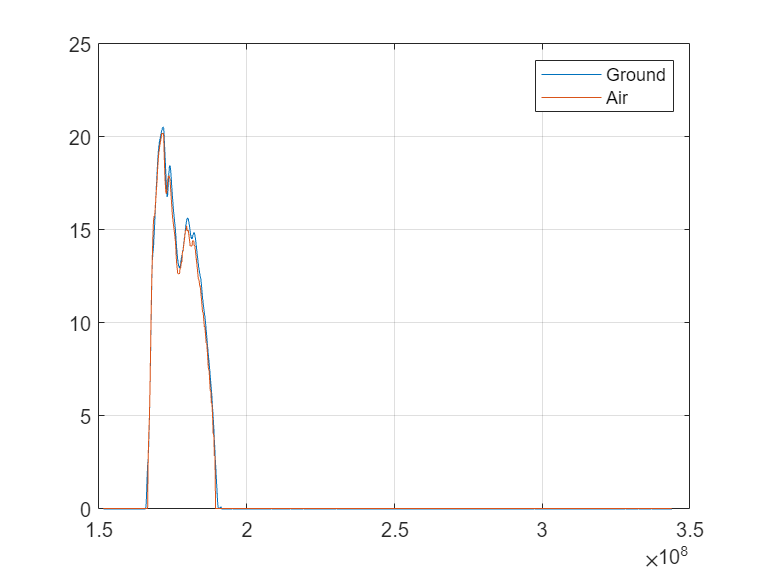



plot(T.Timestamp,T.("G-Speed [m/s]"),T.Timestamp,T.Airspeed)
hold on
grid on
legend('Ground','Air')
hold off

%Baro and Temp
% Initialize an array to store the indices
closestIndices = zeros(size(GPS_0, 1), 1);

% Loop over each timestamp in the first vector
for i = 1:size(GPS_0, 1)
    % Find the index in the second vector with the closest timestamp
    [~, index] = min(abs(BARO_0(:,2) - GPS_0(i,2)));
    % Store the index in the array
    closestIndices(i) = index;
end

% Now, closestIndices contains the indices in the second vector corresponding to the closest timestamps in the first vector
closestIndices

closestIndices =      2
     4
     6
     8
    10
    12
    14
    16
    18
    20




Barometer = BARO_0(closestIndices,5)

Barometer = 1.0e+04 *

    9.6096
    9.6094
    9.6097
    9.6094
    9.6094
    9.6096
    9.6097
    9.6097
    9.6097
    9.6094


T.Barometer = Barometer

T = 963×15 table
    Timestamp     Timestamp Daytime    ALT     Lat       Long     G-Speed [m/s]    GroundCourse      GyroX        GyroY        GyroZ       AcceX     AcceY      AcceZ     Airspeed    Barometer
    __________    _________________    ___    ______    ______    _____________    ____________    _________    _________    _________    _______    ______    _______    ________    _________

    1.5145e+08       2.5487e+08         0     47.343    8.2572            0           21

Temperature = BARO_0(closestIndices,6)

Temperature =    32.0600
   32.0600
   32.0700
   32.0600
   32.0600
   32.0700
   32.0700
   32.0700
   32.0700
   32.0700


T.Temperature = Temperature

T = 963×16 table
    Timestamp     Timestamp Daytime    ALT     Lat       Long     G-Speed [m/s]    GroundCourse      GyroX        GyroY        GyroZ       AcceX     AcceY      AcceZ     Airspeed    Barometer    Temperature
    __________    _________________    ___    ______    ______    _____________    ____________    _________    _________    _________    _______    ______    _______    ________    _________    ___________

    1.5145e+08       2.5

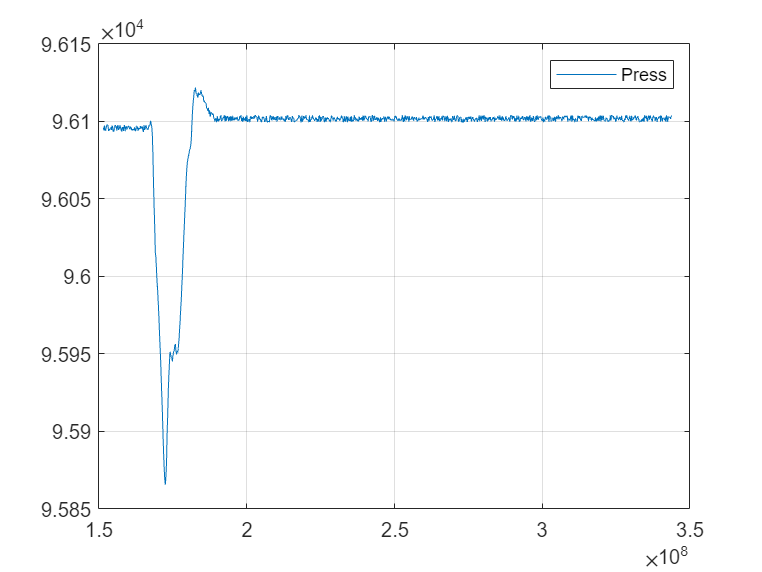


plot(T.Timestamp,T.Barometer)
hold on
grid on
legend('Press')
hold off

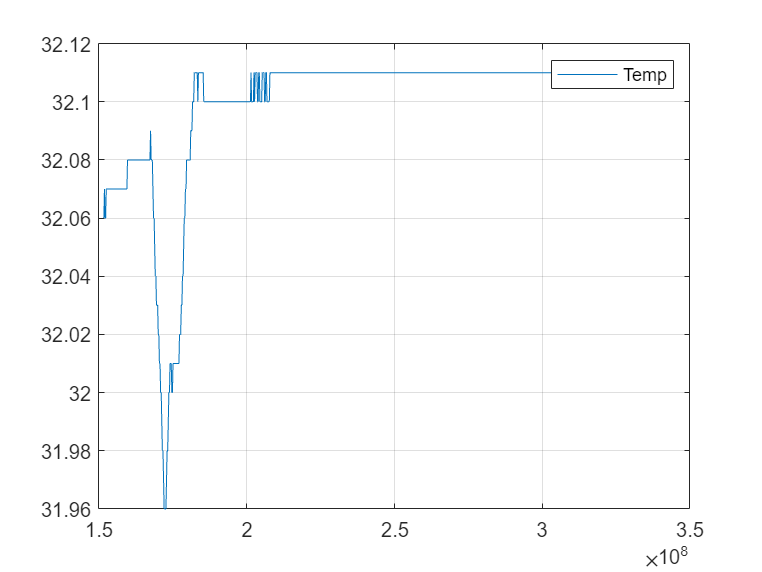


plot(T.Timestamp,T.Temperature)
hold on
grid on
legend('Temp')
hold off

% Energie
Energie =nan(1,length(GPS_0(:,2)));
g= 9.81

g = 9.8100


for i = 1:size(GPS_0, 1)
    Energie(i) = 1./(2*g)*(T.Airspeed(i))^2+T.ALT(i);
end

Energie

Energie =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



% Ableitung
EnergieAb =nan(1,length(GPS_0(:,2)));
for i = 2:(length(Energie))
    EnergieAb(i) = Energie(i)-Energie(i-1);
end

EnergieAb

EnergieAb =    NaN     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



T.Energie = Energie';
T.EnergieAbleitung = EnergieAb'

T = 963×18 table
    Timestamp     Timestamp Daytime    ALT     Lat       Long     G-Speed [m/s]    GroundCourse      GyroX        GyroY        GyroZ       AcceX     AcceY      AcceZ     Airspeed    Barometer    Temperature     Energie      EnergieAbleitung
    __________    _________________    ___    ______    ______    _____________    ____________    _________    _________    _________    _______    ______    _______    ________    ________

%Heading Roll Pitch Yaw
% Initialize an array to store the indices
closestIndices = zeros(size(GPS_0, 1), 1);

% Loop over each timestamp in the first vector
for i = 1:size(GPS_0, 1)
    % Find the index in the second vector with the closest timestamp
    [~, index] = min(abs(ATT(:,2) - GPS_0(i,2)));
    % Store the index in the array
    closestIndices(i) = index;
end

% Now, closestIndices contains the indices in the second vector corresponding to the closest timestamps in the first vector
closestIndices

closestIndices =      5
    10
    15
    20
    25
    30
    35
    40
    45
    50



% Convert into RADIANS and save in Table
ROLL = ATT(closestIndices,4)

ROLL =    -8.4900
   -8.4900
   -8.4900
   -8.4900
   -8.4900
   -8.4900
   -8.4900
   -8.4900
   -8.4900
   -8.4900


ROLL = (ROLL)

ROLL =    -8.4900
   -8.4900
   -8.4900
   -8.4900
   -8.4900
   -8.4900
   -8.4900
   -8.4900
   -8.4900
   -8.4900


T.Roll = ROLL

T = 963×19 table
    Timestamp     Timestamp Daytime    ALT     Lat       Long     G-Speed [m/s]    GroundCourse      GyroX        GyroY        GyroZ       AcceX     AcceY      AcceZ     Airspeed    Barometer    Temperature     Energie      EnergieAbleitung    Roll 
    __________    _________________    ___    ______    ______    _____________    ____________    _________    _________    _________    _______    ______    _______    ________


PITCH = ATT(closestIndices,6)

PITCH =     3.8300
    3.8300
    3.8300
    3.8300
    3.8300
    3.8300
    3.8300
    3.8300
    3.8300
    3.8300


PITCH = (PITCH)

PITCH =     3.8300
    3.8300
    3.8300
    3.8300
    3.8300
    3.8300
    3.8300
    3.8300
    3.8300
    3.8300


T.Pitch = PITCH

T = 963×20 table
    Timestamp     Timestamp Daytime    ALT     Lat       Long     G-Speed [m/s]    GroundCourse      GyroX        GyroY        GyroZ       AcceX     AcceY      AcceZ     Airspeed    Barometer    Temperature     Energie      EnergieAbleitung    Roll     Pitch
    __________    _________________    ___    ______    ______    _____________    ____________    _________    _________    _________    _______    ______    _______


YAW = ATT(closestIndices,8)

YAW =    91.6800
   91.6800
   91.6800
   91.6800
   91.6800
   91.6800
   91.6800
   91.6800
   91.6800
   91.6800


YAW = (YAW)

YAW =    91.6800
   91.6800
   91.6800
   91.6800
   91.6800
   91.6800
   91.6800
   91.6800
   91.6800
   91.6800


T.Yaw = YAW

T = 963×21 table
    Timestamp     Timestamp Daytime    ALT     Lat       Long     G-Speed [m/s]    GroundCourse      GyroX        GyroY        GyroZ       AcceX     AcceY      AcceZ     Airspeed    Barometer    Temperature     Energie      EnergieAbleitung    Roll     Pitch     Yaw 
    __________    _________________    ___    ______    ______    _____________    ____________    _________    _________    _________    _______    ______

%Humidity
T.Humidity = repmat(20, height(T), 1)

T = 963×22 table
    Timestamp     Timestamp Daytime    ALT     Lat       Long     G-Speed [m/s]    GroundCourse      GyroX        GyroY        GyroZ       AcceX     AcceY      AcceZ     Airspeed    Barometer    Temperature     Energie      EnergieAbleitung    Roll     Pitch     Yaw     Humidity
    __________    _________________    ___    ______    ______    _____________    ____________    _________    _________    _________    _______

FontSize = 30;
LineWidth = 100;
gx = geoscatter(T.Lat(2:end),T.Long(2:end),LineWidth)

gx =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
          LineWidth: 0.5000
       LatitudeData: [47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 … ]
      LongitudeData: [8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 … ]
              ZData: [1×0 double]
           SizeData: 100
              CData: [0 0.4470 0.7410]

  Show 

hold on;
lgd=legend("Flightpath",'Location','northwest')

lgd =   Legend (Flightpath) with properties:

         String: {'Flightpath'}
       Location: 'northwest'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.1762 0.8579 0.1875 0.0429]
          Units: 'normalized'

  Show all properties


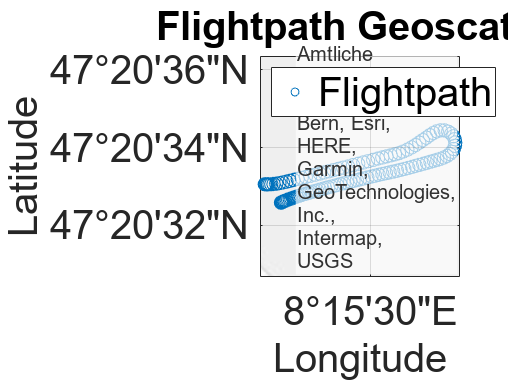

title("Flightpath Geoscatter")
fontsize(lgd,FontSize,'points');
fontsize(gca, FontSize,'points');
hold off;

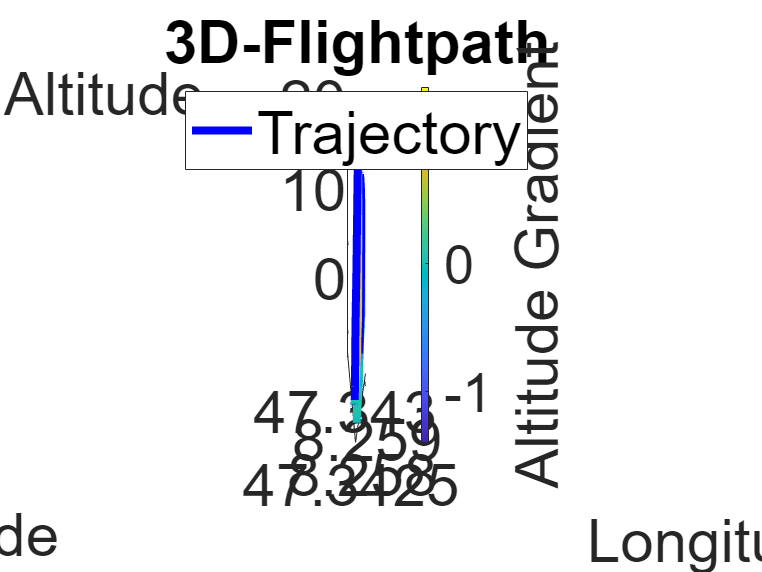

LineWidth = 4;
FontSize = 30;
% Plot the 3D trajectory
plot3(T.Long(2:end), T.Lat(2:end), T.ALT(2:end), 'b-', 'LineWidth', LineWidth);
hold on;

% Initialize gradient vector
gradient = zeros(size(T.ALT));

% Calculate gradient for each data point
for i = 2:length(T.ALT)
    altdiff = T.ALT(i) - T.ALT(i-1);
    gradient(i) = altdiff;
end

% Map gradient to colors
cd = colormap('parula');
cd = interp1(linspace(min(gradient), max(gradient), length(cd)), cd, gradient);
cd = uint8(cd' * 255);
cd(4, :) = 255;

% Plot lines from ground to each data point with different colors based on gradient
for i = 2:length(T.Long)
    % Select color for this line
    color = cd(:, i);
    
    % Plot the line with the determined color
    plot3([T.Long(i) T.Long(i)], [T.Lat(i) T.Lat(i)], [0 T.ALT(i)], 'Color', color, 'LineWidth', LineWidth);
end

% Create a colorbar
c = colorbar;
c.Label.String = 'Altitude Gradient';
caxis([min(gradient), max(gradient)]);
title("3D-Flightpath")
xlabel('Longitude');
ylabel("Latitude");
zlabel("Altitude");
% Create legend
lgd=legend('Trajectory', 'Location', 'Best');
fontsize(lgd,FontSize,'points');
fontsize(gca, FontSize,'points');

hold off;

% Create SAVE Tasble with correct data sequence
%SaveTable = table(T.Timestamp,T.("Timestamp Daytime"),T.Humidity,T.("G-Speed [m/s]"),T.Airspeed,T.Temperature,T.Barometer,T.Long,T.Lat,T.ALT,T.Roll,T.Pitch,T.Yaw,T.GroundCourse,T.Energie,T.EnergieAbleitung,T.GyroX,T.GyroY,T.GyroZ,T.AcceX,T.AcceY,T.AcceZ,'VariableNames', {'Time since System Start [us]','Week time [milliseconds since start of GPS week]','Humidity [%]','Groundspeed [m/s]','Airspeed [m/s]','Temperature [deg C]','Airpressure [kPas]','Longitude','Latitude','Flight Height [m]','Roll [deg]','Pitch [deg]','Yaw [deg]','Ground course [deg]','Energie [m]','Energieableitung [m/s]','GyroX [rad/s]','GyroY [rad/s]','GyroZ [rad/s]','AcceX [m/s/s]','AcceY [m/s/s]','AcceZ [m/s/s]'}) 
SaveTable = table(T.Timestamp,T.("Timestamp Daytime"),T.Humidity,T.("G-Speed [m/s]"),T.Airspeed,T.Temperature,T.Barometer,T.Long,T.Lat,T.ALT,T.Roll,T.Pitch,T.Yaw,T.GroundCourse,T.Energie,T.GyroX,T.GyroY,T.GyroZ,T.AcceX,T.AcceY,T.AcceZ,'VariableNames', {'Time since System Start [us]','Week time [milliseconds since start of GPS week]','Humidity [%]','Groundspeed [m/s]','Airspeed [m/s]','Temperature [deg C]','Airpressure [kPas]','Longitude','Latitude','Flight Height [m]','Roll [deg]','Pitch [deg]','Yaw [deg]','Ground course [deg]','Energie [m]','GyroX [rad/s]','GyroY [rad/s]','GyroZ [rad/s]','AcceX [m/s/s]','AcceY [m/s/s]','AcceZ [m/s/s]'}) 

SaveTable = 963×21 table
    Time since System Start [us]    Week time [milliseconds since start of GPS week]    Humidity [%]    Groundspeed [m/s]    Airspeed [m/s]    Temperature [deg C]    Airpressure [kPas]    Longitude    Latitude    Flight Height [m]    Roll [deg]    Pitch [deg]    Yaw [deg]    Ground course [deg]    Energie [m]    GyroX [rad/s]    GyroY [rad/s]    GyroZ [rad/s]    AcceX [m/s/s]    AcceY [m/s/s]    AcceZ [m/s/s]
    ____________________________    ________________________________________________    ____________    _________________    ____

writetable(SaveTable,'ShortFlight.csv','Delimiter',';')    

timediff(1) =0 ;
for i= 2:length(T.Timestamp)

   timediff(i-1) = T.Timestamp(i)-T.Timestamp(i-1);


end

i = 1:length(timediff)

i =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


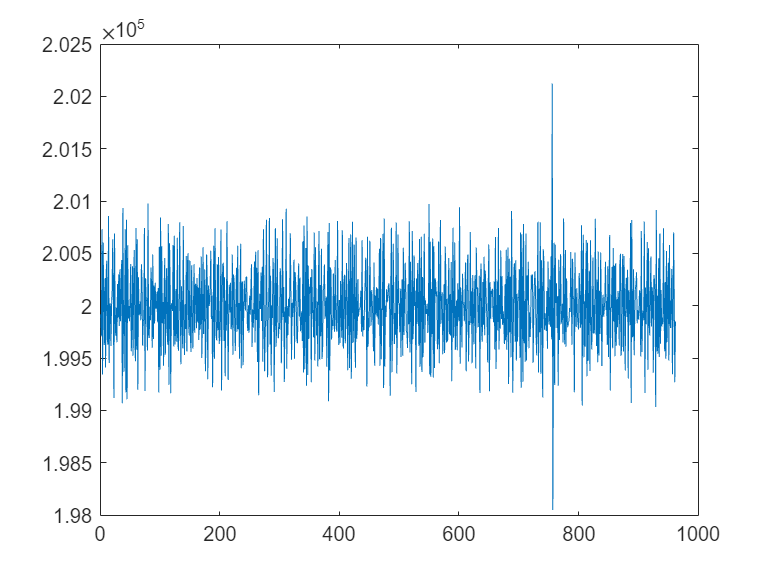

plot(i,timediff)

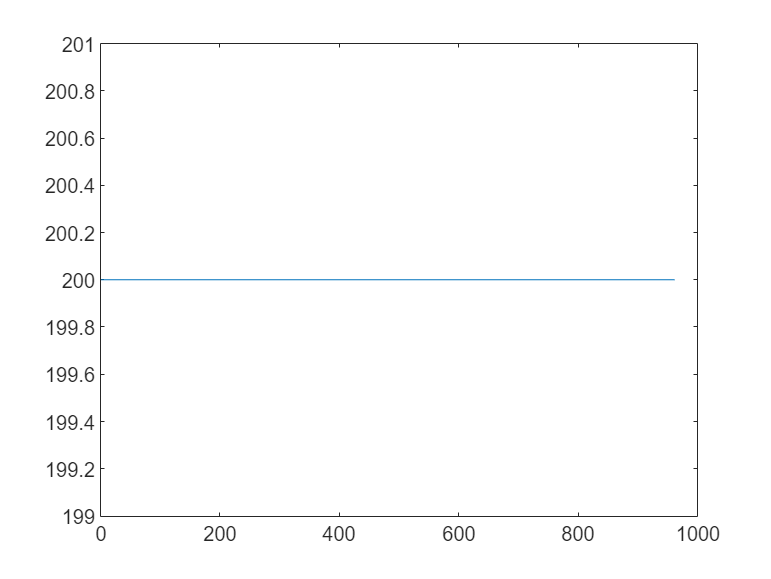


timediff(1) =0 ;
for i= 2:length(T.("Timestamp Daytime"))

   timediffDay(i-1) = T.("Timestamp Daytime")(i)-T.("Timestamp Daytime")(i-1);


end

i = 1:length(timediffDay);
plot(i,timediffDay)

index = 1;
for i=1:length(T.Timestamp)

    if T.Airspeed(i) > 1
        validYaw(index) = T.Yaw(i);
        validCourse(index) = T.GroundCourse(i);
        validAirspeed(index) = T.Airspeed(i);
        validGroundspeed(index) = T.("G-Speed [m/s]")(i);
        index = index + 1;
    end

end

headingdiff = abs(validCourse-validYaw);


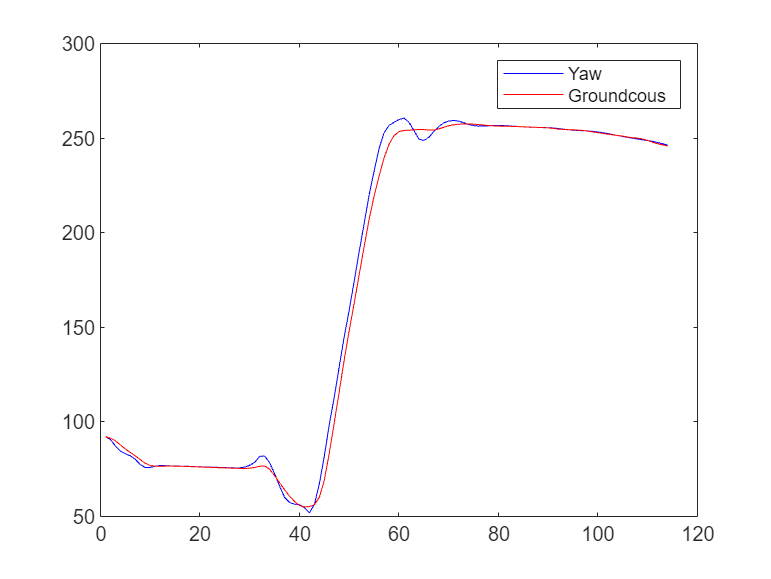

TF = isoutlier(headingdiff,"percentiles",[0 98]);

i = 1:length(validYaw);
plot(i,validYaw,'b')
hold on
plot (i,validCourse,'r')
legend('Yaw','Groundcous')
hold off;

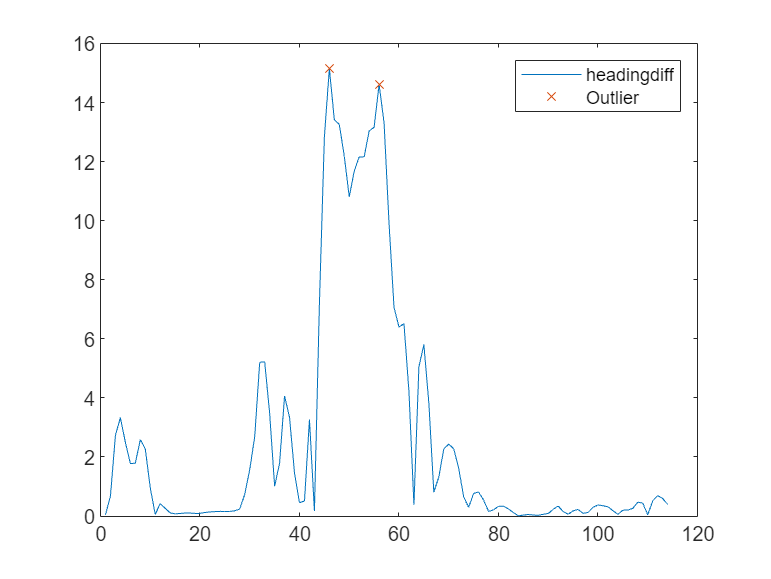


i = 1:length(headingdiff);
plot(i,headingdiff)
hold on;
plot(i(TF),headingdiff(TF),"x")
legend('headingdiff','Outlier')
hold off;

%head_mean = mean(headingdiff);
%headingdiff(TF) = head_mean;
%i = 1:length(headingdiff);
%plot(i,headingdiff)

i=sqrt(-1)

i = 0.0000 + 1.0000i

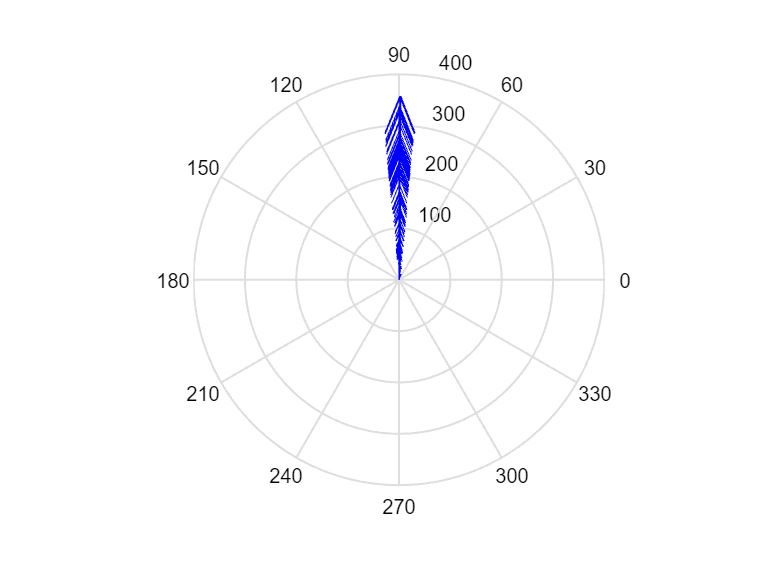




for j=1:length(validYaw)
    V_PAir(j) = validAirspeed(j)*exp(i*(deg2rad(validYaw(j))));
    V_PGround(j) = validGroundspeed(j)*exp(i*(deg2rad(validCourse(j))));
    V_PWind(j) = V_PGround(j)-V_PAir(j);
    Wind_angle(j) = rad2deg(angle(V_PWind(j)));
    if Wind_angle(j) < 0
        Wind_angle(j)= 360-abs(Wind_angle(j));
        Wind_ampl(j) = abs(V_PWind(j));
    else
        Wind_angle(j);
        Wind_ampl(j) = abs(V_PWind(j));
    end
end


h1 = compass(Wind_ampl, Wind_angle, 'b');

j = 1:length(T.Energie);
figure(1);clf;
yyaxis left
plot(j,T.Energie)
ylabel('Energy [m]');
ylim([0 140])
hold on;
yyaxis right
plot(j,T.EnergieAbleitung)
ylabel('Energyableitung [m/s]');
ylim([0 5])
grid on;
xlabel('Messpunkt');
title('Energy und Ableitung');
lgd=legend(["Energy", "Ableitung"])

lgd =   Legend (Energy, Ableitung) with properties:

         String: {'Energy'  'Ableitung'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.7024 0.8234 0.1839 0.0774]
          Units: 'normalized'

  Show all properties


hold off;